%initialization skript
p1 = 4;  %PID variables for the angular velocity
d1 = 2;

p2 = 5;  %PID variables for the velocity controller 
d2 = 4;


Goal = [100, 100]; %desired position (x,y)

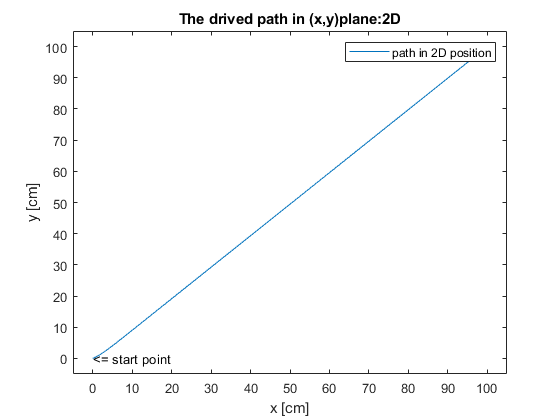

%ploting trajectory
figure
x = out.CartCoords.Data(:,1);
y = out.CartCoords.Data(:,2);
t = out.CartCoords.Data(:,3);
figure
    plot(x,y)
    title('The drived path in (x,y)plane:2D')
    text(0,0,"<= start point")
    xlabel('x [cm]');
    ylabel('y [cm]');
    legend('path in 2D position')
    xlim([-5 105]);
    ylim([-5 105]);

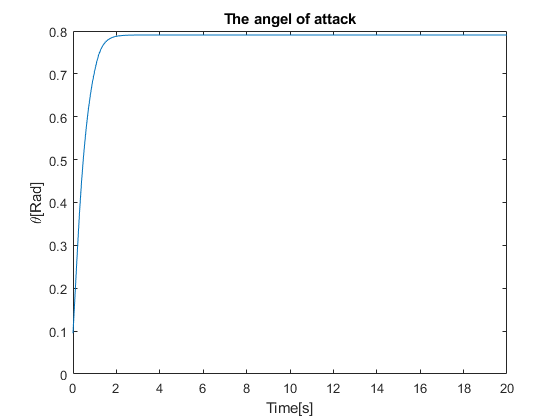

figure
    plot(out.CartCoords.Time, t)
    title('The angel of attack')
    xlabel('Time[s]');
    ylabel('\theta[Rad]');

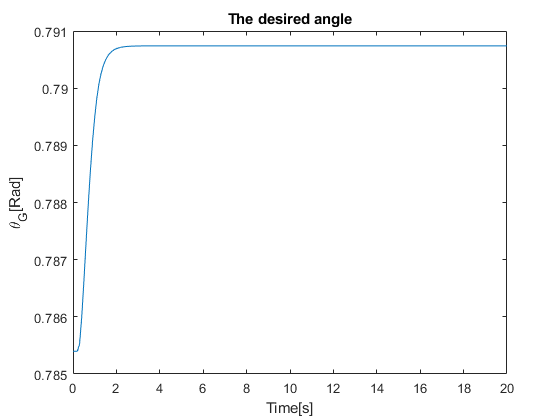

figure
    plot(out.CartCoords.Time,out.CartCoords.Data(:,5))
    title('The desired angle')
    xlabel('Time[s]');
    ylabel('\theta_{G}[Rad]');

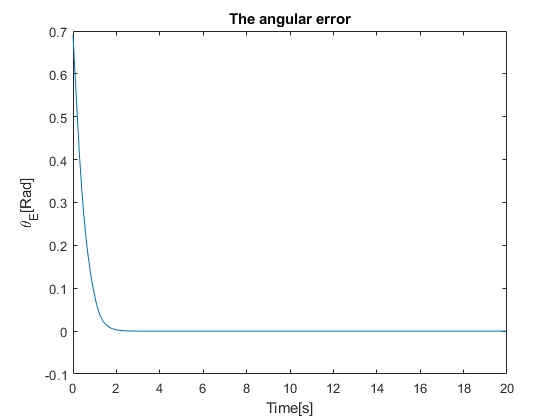

figure
    plot(out.CartCoords.Time,out.CartCoords.Data(:,4))
    title('The angular error')
    xlabel('Time[s]');
    ylabel('\theta_{E}[Rad]');

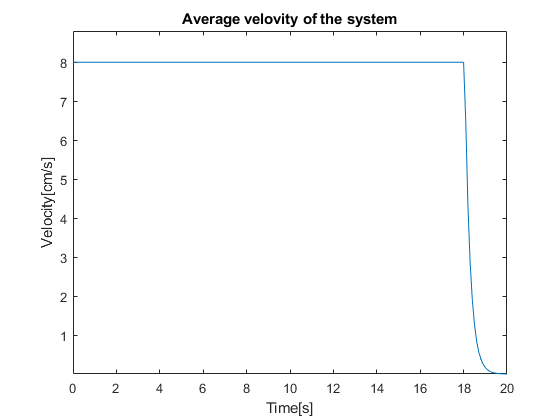

figure
    plot(out.velocities.Time,out.velocities.Data(:,1))
    title('Average velovity of the system')
    xlabel('Time[s]');
    ylabel('Velocity[cm/s]');
    ylim([min(out.velocities.Data(:,1))*1.1 max(out.velocities.Data(:,1))*1.1])

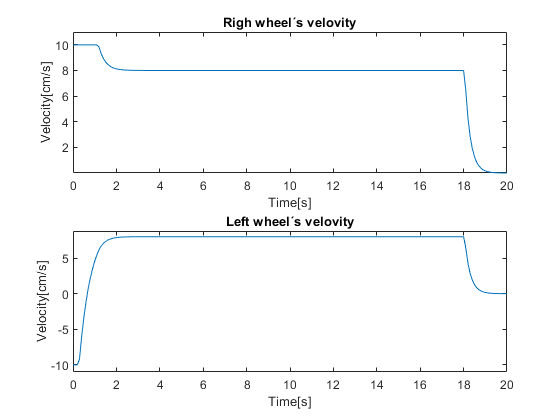

figure
subplot(2,1,1)
    plot(out.velocities.Time,out.velocities.Data(:,2))
    title('Righ wheel´s velovity')
    xlabel('Time[s]');    
    ylabel('Velocity[cm/s]');
    ylim([min(out.velocities.Data(:,2))*1.1 max(out.velocities.Data(:,2))*1.1])
subplot(2,1,2)
    plot(out.velocities.Time,out.velocities.Data(:,3))
    title('Left wheel´s velovity')
    xlabel('Time[s]');
    ylabel('Velocity[cm/s]');
    ylim([min(out.velocities.Data(:,3))*1.1 max(out.velocities.Data(:,3))*1.1])
subplot(2,1,1)

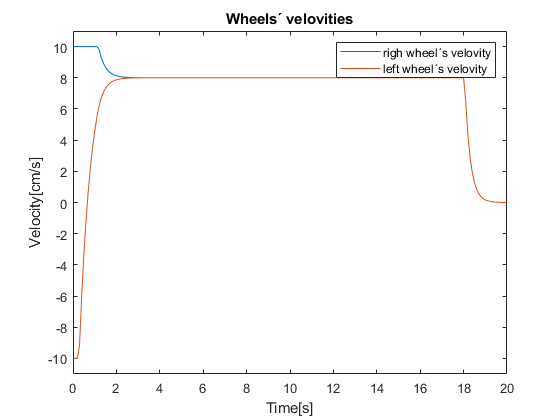

figure
    plot(out.velocities.Time,out.velocities.Data(:,2))
    hold on
    plot(out.velocities.Time,out.velocities.Data(:,3))
    title('Wheels´ velovities')
    legend('righ wheel´s velovity','left wheel´s velovity')
    xlabel('Time[s]');
    ylabel('Velocity[cm/s]');
    ylim([-11 11])

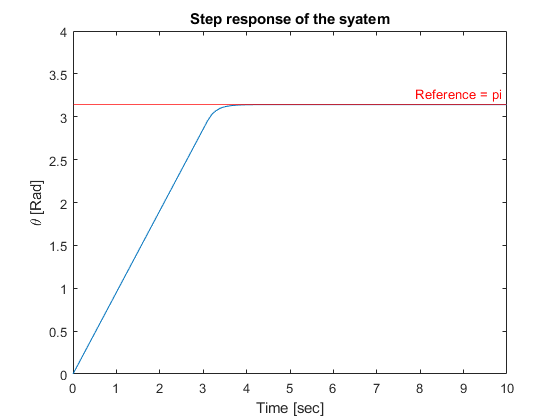

    plot(out.theta.Time, out.theta.Data(:,1))
    title('Step response of the syatem')
    xlabel('Time [sec]');
    ylabel('\theta [Rad]');
    xlim([0 10]);
    ylim([0 4]);
    yline(pi, 'R','Reference = pi');